clear, clc, close all;
load("sim_data_final.mat");
stopIdx = 7001;

Simdata

sim_x = reshape(out.x.Data, [10001, 1]);
sim_x = sim_x(1:stopIdx, :);

sim_x_d = reshape(out.x_d.Data, [10001, 1]);
sim_x_d = sim_x_d(1:stopIdx, :);

sim_q = reshape(out.q.Data, [10001, 1]);
sim_q = sim_q(1:stopIdx, :);

sim_q_d = reshape(out.q_d.Data, [10001, 1]);
sim_q_d = sim_q_d(1:stopIdx, :);

sim_u = reshape(out.u.Data, [10001, 1]);
sim_u = sim_u(1:stopIdx, :);

Read data from CSV files

Ts = 0.001;  % sec
myData = readmatrix("data_encoder\final_data_4.csv");
myDataSize = size(myData);

Split data into categories

% input u (m/s2)
u = myData(:, 1);

% x (m)
x = myData(:, 2);

% x_dot (m/s)
x_d = myData(:, 3);

% q (rad) -- unwrapped
q = myData(:, 4);

% q_wrapped (rad)
q_w = atan2(sin(q), cos(q));

% q_dot (rad/s)
q_d = myData(:, 5);

for idx = 1:length(q_d)
    if q_d(idx) ~= 0
        break;
    end
end
disp(idx)

        3463



myData = myData(idx:end, :);
myDataSize = size(myData);
stopIdx = 7001;
% generate time
t = ((linspace(1, myDataSize(1), myDataSize(1)) - 1).*Ts)';
t = t(1:stopIdx,:);
% input u (m/s2)
u = myData(1:stopIdx, 1);

% x (m)
x = myData(1:stopIdx, 2);

% x_dot (m/s)
x_d = myData(1:stopIdx, 3);

% q (rad) -- unwrapped
q = myData(1:stopIdx, 4);

% q_wrapped (rad)
q_w = atan2(sin(q), cos(q));

% q_dot (rad/s)
q_d = myData(1:stopIdx, 5);

Plotting

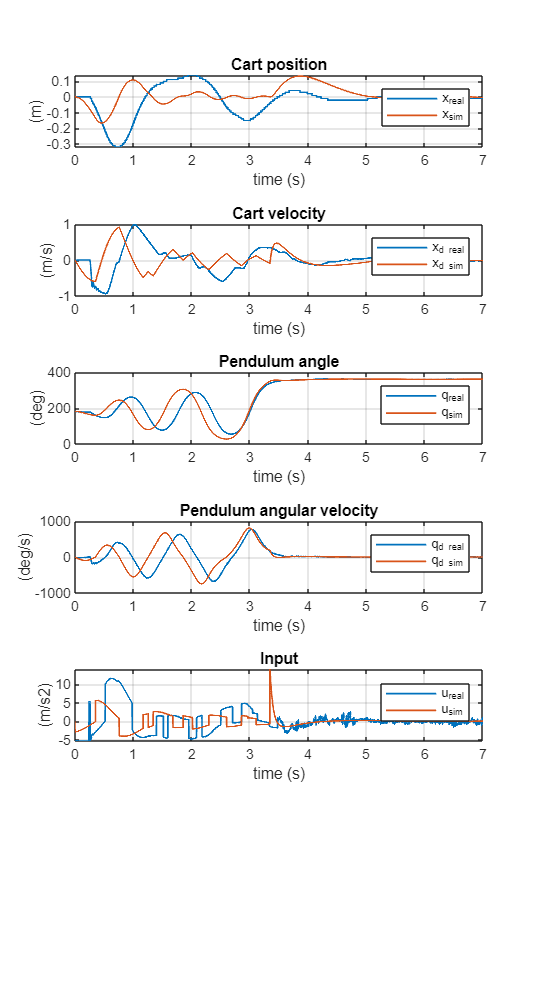

plotMode = 3;  % 1-real, 2-sim, 3-comparison

tiledlayout(6, 1, "TileIndexing","rowmajor");
scaleCoeff = 3;
fig = gcf;
fig.Position(1) = fig.Position(1) / scaleCoeff;
fig.Position(2) = fig.Position(2) / scaleCoeff;
fig.Position(3) = scaleCoeff * fig.Position(3);
fig.Position(4) = 2.5*scaleCoeff * fig.Position(4);
nexttile;
if plotMode == 1
    plot(t, x, "LineWidth", 1, "Color", [0 0 0]);
elseif plotMode == 2
    plot(t, sim_x, "LineWidth", 1, "Color", [0 0 0]);
elseif plotMode == 3
    plot(t, x, t, sim_x, "LineWidth", 1);
    legend("x_{real}", "x_{sim}");
end
title('Cart position');
xlabel("time (s)");
ylabel("(m)");
grid on;

nexttile;
if plotMode == 1
    plot(t, x_d, "LineWidth", 1, "Color", [0 0 0]);
elseif plotMode == 2
    plot(t, sim_x_d, "LineWidth", 1, "Color", [0 0 0]);
elseif plotMode == 3
    plot(t, x_d, t, sim_x_d, "LineWidth", 1);
    legend("x_{d real}", "x_{d sim}");
end
title('Cart velocity');
xlabel("time (s)");
ylabel("(m/s)");
grid on;

nexttile;
if plotMode == 1
    plot(t, rad2deg(q), "LineWidth", 1, "Color", [0 0 0]);
elseif plotMode == 2
    plot(t, sim_q, "LineWidth", 1, "Color", [0 0 0]);
elseif plotMode == 3
    plot(t, rad2deg(q), t, sim_q, "LineWidth", 1);
    legend("q_{real}", "q_{sim}");
end
title('Pendulum angle');
xlabel("time (s)");
ylabel("(deg)");
grid on;

nexttile;
if plotMode == 1
    plot(t, rad2deg(q_d), "LineWidth", 1, "Color", [0 0 0]);
elseif plotMode == 2
    plot(t, sim_q_d, "LineWidth", 1, "Color", [0 0 0]);
elseif plotMode == 3
    plot(t, rad2deg(q_d), t, sim_q_d, "LineWidth", 1);
    legend("q_{d real}", "q_{d sim}");
end
title('Pendulum angular velocity');
xlabel("time (s)");
ylabel("(deg/s)");
grid on;

nexttile;
if plotMode == 1
    plot(t, u, "LineWidth", 1, "Color", [0 0 0]);
elseif plotMode == 2
    plot(t, sim_u, "LineWidth", 1, "Color", [0 0 0]);
elseif plotMode == 3
    plot(t, u, t, sim_u, "LineWidth", 1);
    legend("u_{real}", "u_{sim}");
end
title('Input');
xlabel("time (s)");
ylabel("(m/s2)");
grid on;